# Técnicas de procesamiento de señales y datos (MUIE)

## Ejercicio práctico bloque 4.1.2. Efecto del aliasing (v3.0)

### Objetivo

El objetivo de este ejercicio es la comprension del impacto del aliasing en el espectro DFT de las señales procesadas. Disculpad que a veces no aparezcan tildes, pero al cambiar de version de matlab, hay un bug que no permite escribirlas.

### Desarrollo

Se dispone de una señal x(t) de duración 1 segundo, que está compuesta por una señal continua de amplitud 5, a la que se suman 6 sinuoidales de frecuencias 1KHz, 2KHz, 4KHz, 8KHz, 10KHz y 16KHz, cuyas amplitudes son 1, 2, 4, 8, 10 y 16, respectivamente. Implemente un script en Matlab que realice las siguientes acciones:

- Borre variables, figuras y ventana de comandos:

clear all;
close all force;
clc;

- Genere una señal discreta x1[n] muestreando x(t) a la frecuencia que considere que debería hacerlo, dejando margen .

f            = [ 1000 2000 4000 8000 10000 16000 ];
timeDuration = 1;
dcComponent  = 5;
amplitude    = [    1    2    4    8    10    16 ];
phase        = [    0    0    0    0     0     0 ];
%fs1          = 2^16;
fs1 = 60e3 ;

[ x1, numSamples1, timeIndexes1 ] = generateSignal(fs1, timeDuration, f, amplitude, phase);
x1           = dcComponent + x1;

- Genere y dibuje el módulo de la fft de x1[n] y discuta brevemente en un comentario si su resultado es coherente con lo que esperaba dado el contenido espectral de x1(t), en cuanto a posiciones en frecuencia y amplitud de las componentes observadas (en estos casos es importante normalizar correctamente la fft). Cambie la frecuencia de muestreo a un valor que considere razonable y discuta el resultado.

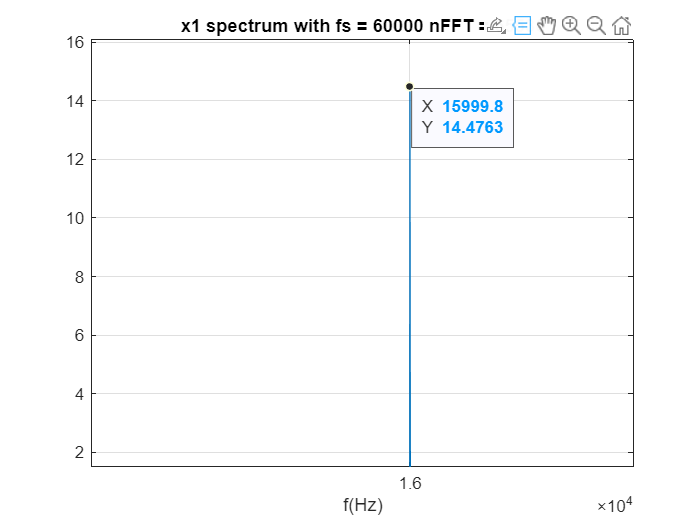

nFFT1 = 2^nextpow2(numSamples1);      % To make the FFT as fast as possible
%nFFT1 = 1024;
fftX1       = 2 * fft(x1, nFFT1) / numSamples1;   % normalize properly
fftX1(1)    = fftX1(1) / 2;
fftX1(end/2+1)  = fftX1(end/2+1) / 2;

fftX1M      = fftshift(abs(fftX1));        % shift to have f=0Hz at middle of freq axis 
fftIndexes1 = fs1 / nFFT1 * (-nFFT1/2:(nFFT1/2-1)); % frequency values for each fft sample
[M, mIdx]   = max(fftX1M);

plot(fftIndexes1, fftX1M)
xlim([ -fs1/2 fs1/2])
title( ['x1 spectrum with fs = ', num2str(fs1), ' nFFT = ', num2str(nFFT1) ])
xticks([-20000:4000:20000])
xlim([-fs1/2 fs1/2]) % JMG para ajustar bien ejes
xlabel('f(Hz)')
grid on

% Comentario y discusion: 
% + Verifique si el contenido espectral
%   es el esperado, tanto desde el punto de vista de la simetria con respecto
%   a f=0, como a la posicion y amplitudes de las componentes frecuenciales. 
% + Discuta si estamos viendo realmente deltas en frecuencia (intente hacer zoom para
%   verificarlo) y justifique lo que observe. 
% + ¿Que valor ha usado como frecuencia de muestreo alternativa y con 
%   que criterio lo ha elegido? ¿Ha observado alguna diferencia en las
%   amplitudes del espectro con esa nueva frecuencia de muestreo?


% El contenido espectral es efectivamente el esperado. 
% En primera instancia, se observa un espectro espejado respecto al eje de amplitudes
% (eje y), lo cual es esperado para una señal real. En segundo lugar, se
% observan aparentes deltas (a simple vista, sin realizar zoom) y la componente
% DC, en las posiciones en frecuencia correctas, ya que el eje tiene una
% escala de 10^4 Hz. Y además en las amplitudes correctas. 

% Se observa una frecuencia de muestreo de fs1 = 65536 Hz, como la frecuencia máxima de la señal
% es de 16000 Hz, cumple con Nyquist. A su vez, en principio, la
% ventana debería ocupar un ancho de ( -fs1/2 ; fs1/2 ), sin embargo, la línea
% " xticks([-20000:4000:20000]) " limita el rango de representación de
% frecuencias de la FFT sin alterar la frecuencia de muestreo ni la resolución. 

% Por su parte, la línea "fftX1 = 2 * fft(x1, nFFT1) / numSamples1 " se
% encarga de normalizar a amplitudes reales en la FFT. 

% La resolución espectral es deltaf = fs1 / nFFT1 = 1 Hz. Por otra parte, al realizar un zoom 
% al tono de 1000 Hz,se observa una delta perfecta en este lugar, o mas bien una representación 
% triangular debido a la interpolación del plot(). 
% Es decir, amplitud 0 para 999 Hz y 1001 Hz, y en medio amplitud 1 en 1000 Hz. 
% El resultado de la interpolación es una forma /\. 

% Lo esperable, según lo visto en la teoría de TDPS, sería ver una forma de
% sinc() al realizar un zoom lo suficientemente grande a una de las
% "deltas" de la FFT. Sin embargo, este no fue el caso. 
% Como las frecuencias a representar "f = [ 1000 2000 4000 8000 10000 16000 ]" 
% son además multiplos de 1 Hz, la resolución, esto genera que el siguiente
% punto de representación de la FFT "caiga" justo en el cruce por cero de
% esa sinc, luego MATLAB interpola linealmente todos estos cruces por cero hasta 
% llegar al siguiente tono a representar, por esto es que no vemos la sinc. 


% Ahora bien, si cambiamos esa frecuencia de muestreo de tal manera que la resolución 
% no sea múltiplo de los tonos de la señal a representar, entonces veremos
% la sinc al hacer zoom. Se opta por fs1 = 60 kHz. Esto resulta en una
% resolución de 0.915 Hz. Con esta frecuencia de muestreo, si se observa la
% sinc y sus lobulos laterales al hacer zoom. Además, la amplitud del tono
% se ve disminuida. 

% Concretamente, la amplitud del pico máximo cae a 0.907 leídos a 999,756
% Hz. Mientras que el valor siguiente de lectura es 0.404 leídos a 1000.67 Hz. 
% Adicionalmente, del workspace se lee el máximo de la señal se encuentra en 15293 Hz, con una
% amplitud de 14,476. Es decir, lejos del punto (16kHz,16) esperado.  
% Esto se debe a que los puntos donde la FFT hace su medida, tambien llamados bins, se desplazaron 
% y ahora no "caen justo" en donde teníamos señal, como si ocurria con fs
% de 65536 Hz. Es decir, nuestra señal "cae" en la zona de interpolación, y
% no podemos leer su valor fehacientemente en ese punto. De hecho, si
% intentaramos extraer el valor de amplitud de esta interpolación el
% resultado está en torno a 0.4 y 0.6 (la mitad del valor real) lo cual
% no es cierto. Eso si, la sinc() verdadera si está centrada en 1000
% Hz con valor 1 de amplitud, solo que la estamos evaluando en puntos
% diferentes (en 999,756 y 1000,67 Hz) y luego MATLAB los interpola. 

% Se concluye así que, como buena práctica de representación, en pos de
% obtener amplitudes y frecuencias verdaderas, se debe ajustar
% adecuadamente el valor de fs (y la resolución) acorde a la señal a madir,
% por supuesto siempre y cuando sea posible y esta sea conocida.


- Genere ahora una señal discreta x2[n], muestreando x(t) a 10KHz, 

fs2          = 10000;
[ x2, numSamples2, timeIndexes2 ] = generateSignal(fs2, timeDuration, f, amplitude, phase);
x2           = dcComponent + x2;

- Genere y dibuje el módulo de la fft de x2[n]. Compare el espectro con el generado anteriormente y justifique brevemente y en un comentario de su código las diferencias que observe con respecto al caso anterior. Es imprescindible que explique y justifique qué frecuencias aparecen y si las amplitudes deberian verse modificadas, teniendo en cuenta la teoría del impacto del muestreo en el espectro. 

nFFT2 = 2^nextpow2(numSamples2);      % To make the FFT as fast as possible
%nFFT2 = 1024;
fftX2       = 2 * fft(x2, nFFT2) / numSamples2;   % normalize properly
fftX2(1)    = fftX2(1) / 2;
fftX2(end)  = fftX2(end) / 2;
fftX2M      = fftshift(abs(fftX2));        % shift to have f=0Hz at middle of freq axis 
fftIndexes2 = fs2 / nFFT2 * (-nFFT2/2:(nFFT2/2-1)); % frequency values for each fft sample
[M, mIdx]   = max(fftX2M);
%plot(fftIndexes2, amplitude(5)/M*fftX2M)
figure
plot(fftIndexes2, fftX2M)
xlim([ -fs2/2 fs2/2])   
% xlim([ -fs1/2 fs1/2])
title( ['x2 spectrum with fs = ', num2str(fs2), ' nFFT = ', num2str(nFFT2) ])
xticks([-5000:1000:5000])
xlabel('f(Hz)')
grid on
% Comentario y discusion: 
% + Discuta de nuevo si las componentes frecuenciales
%   encajan ahora con la prevision teorica, tanto en su posicion frecuencial
%   como en las amplitudes observadas.